%FILTERING and SEGMENTING

opts.orig_file_dir = "../physionet.org/textdata/";
opts.abp_ann_dir = '../physionet.org/abp_ann/';
opts.segmented_file_dir = "../physionet.org/segmented_data/";
opts.clear_segmented_dir = true; %delete all existing files in segmented file directory
opts.segmented_abp_dir = "../physionet.org/segmented_abp_beats/";

opts.first_record_process = 25;
opts.last_record_process = 25; %use -1 to process all

opts.apply_filter = false;
opts.samp_freq = 125;
opts.filter.type = 'low';
opts.filter.cutoff = 15; %vector if bandpass
opts.filter.order = 3;

opts.apply_hampel_abp = false;
opts.apply_hampel_ppg = true;

opts.flats.derivative_thresh = 1e-3;
opts.flats.window = 300;
opts.flats.window_thresh = 0.5;
opts.min_region_length = opts.samp_freq*60;

opts.num_periods_per_segment = 20;

filterAndSegment(opts);


data = importdata( "../physionet.org/segmented_data/3000393_0016-0001.txt"); 
locOfBeats = importdata( "../physionet.org/segmented_abp_beats/3000393_0016-0001b.txt"); 

[hr_avg, hr_max, hr_most_rec] = heartRate("3000393_0016-0001.txt","../physionet.org/segmented_abp_beats/", opts.samp_freq)

hr_avg = 75.7807

hr_max = 178.5714

hr_most_rec = 68.8073

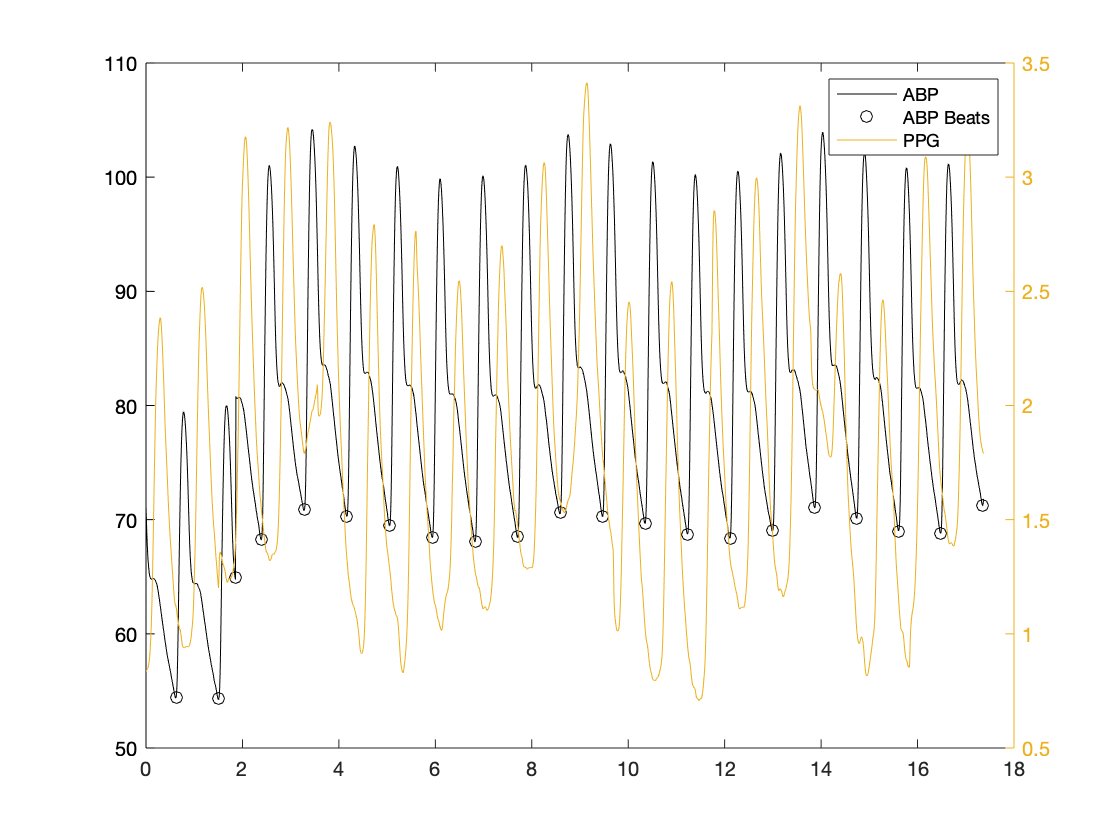


clf
plot(data(:,1), data(:,2)); 
hold on
scatter(data(locOfBeats,1), data(locOfBeats,2))
yyaxis right; 
plot(data(:,1), data(:,3))
legend("ABP", "ABP Beats", "PPG")